x=load("result\x.txt");
usol=load('result\u.txt');

% Import data from text file
params = readtable("D:\source\repos\Chiahwa\HwaQuantum\HwaQuantum\result\params.txt");
t=params.dt*(0:params.nsteps);

usol=usol';
noise_type_str = ["BITFLIP", "DEPOLARIZING", "DEPHASING", "DAMPING"];
filename = strcat('DATA/MAT_',...
    noise_type_str(params.noise_type+1), num2str(params.noise_p),...
    '_lambda',num2str(params.lambda),...
    '_offset',num2str(params.offset),...
    '_dt', num2str(params.dt),...
    '_nqubits',num2str(params.nqubits))

filename = "DATA/MAT_DEPOLARIZING0.001_lambda2_offset2_dt0.005_nqubits9"

save(strcat(filename,'.mat'))

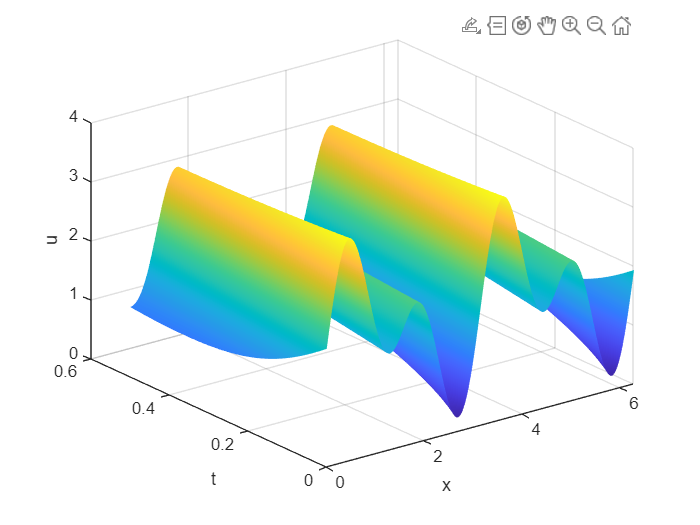

[X,T]=meshgrid(x,t);
surf(X,T,abs(usol'))
xlabel('x')
ylabel('t')
zlabel('u')
shading interp